clc;
clear;
close all;

Lets import received ping signal recorded using a smartphone

[ping_received, Fs] = audioread('2khz10ms.wav');
dt = 1/Fs;
L = length(ping_received)

L = 8192

T = (L-1)*dt;
t = (0:dt:T);

 Plot full signal

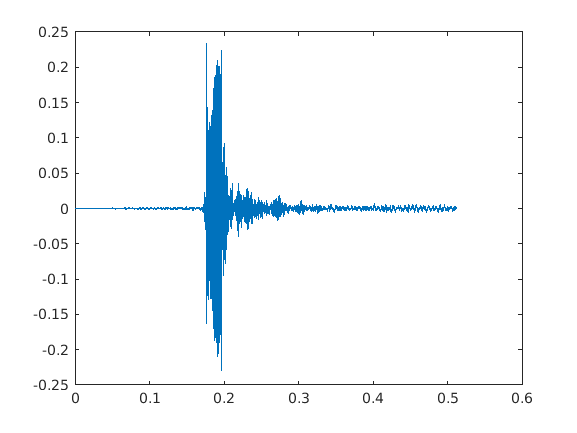

plot(t,ping_received)

Calculate Energy vector

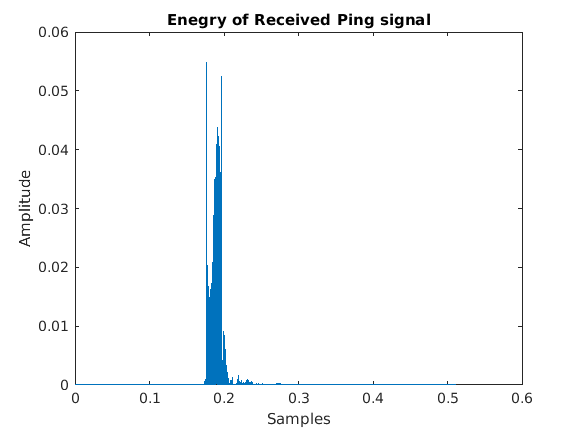

energy_vector = ping_received.^2;
plot(t,energy_vector)
title('Enegry of Received Ping signal')
xlabel('Samples')
ylabel('Amplitude')

Use short (~0.5ms) and long (~5ms) time constant filers

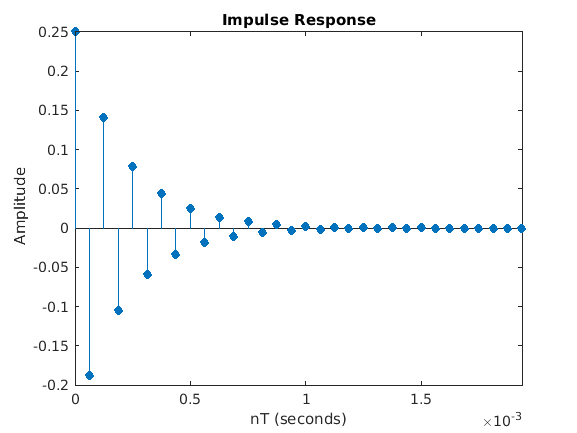

ps = 0.75; % short
pl = 0.97; % long

Num1 = [(1-ps) 0];
Den1 = [1 ps];
Num2 = [(1-pl) 0];
Den2 = [1 pl];

impz(Num1,Den1,32,Fs)

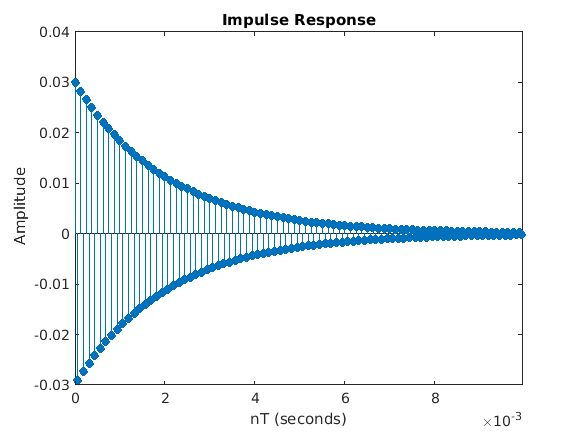

impz(Num2,Den2,160,Fs)


short_energy_sys = tf(Num1, Den1);
long_energy_sys = tf(Num2, Den2);

Pass energy signal through filters

opt_short = lsim(short_energy_sys, energy_vector,t);
opt_long = lsim(long_energy_sys, energy_vector,t);

Find energy spikes

threshold_inp = zeros([L,1]);
for i = 1:1:L
    if ((opt_short(i,1)*opt_long(i,1))~=0)
        threshold_inp(i)=abs(opt_short(i)/opt_long(i));
    end
end

For analysis, plot the output of the filter and output of division

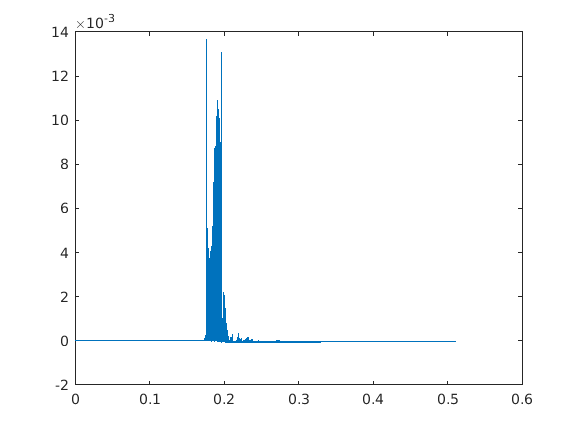

plot(t,opt_short)

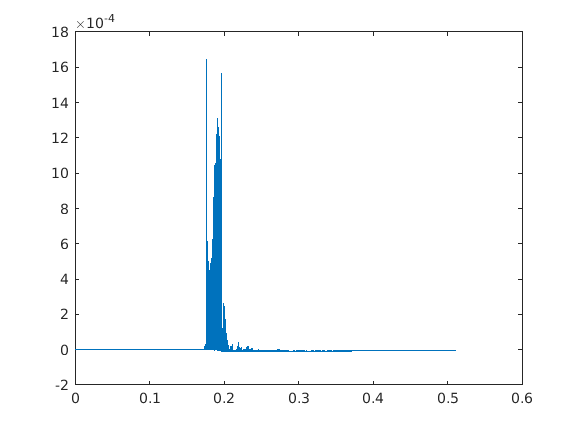

plot(t,opt_long)

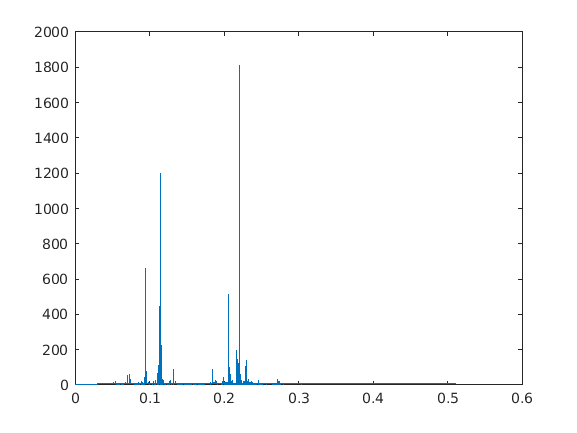

plot(t,threshold_inp)

Now we apply threshold to find onsets

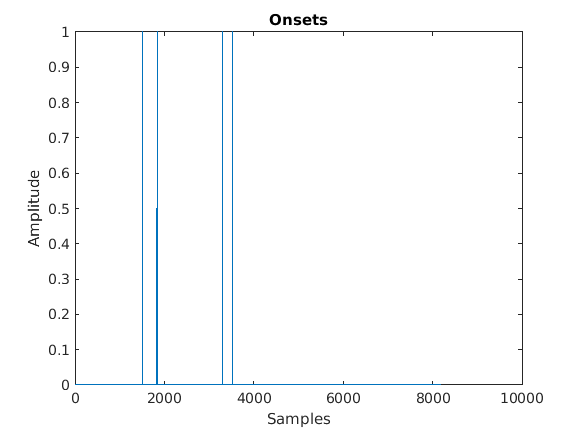

onset = zeros([length(threshold_inp),1]);
count=0;

for i = 1:1:length(threshold_inp)
    if (threshold_inp(i,1)>500)
        onset(i,1)=1;
        count=count+1;
    end
end

plot(onset)
title('Onsets')
xlabel('Samples')
ylabel('Amplitude')

count

count = 4

We see here a count of 4, meaning 75% false positives, which satisifies criteria for high false positives.